# Drone modeling(second_order)

vx and vy are assumed to be decoupled for simplicity of the first controller implementation. The goal is to find the a first order representation of the dynamics of the system. It is worth noting that data was obtained through experiments.

Important to note that velocities are done in local frame 

## vx vy

clear all
close all
test_vx_1_data = './test_result/drone_modelling_result/test_vx_1.csv';
test_vx_2_data = './test_result/drone_modelling_result/test_vx_2.csv';
test_vy_1_data = './test_result/drone_modelling_result/test_vy_1.csv';

[r_1,T_vx_1] = import_data(test_vx_1_data);

Plotting file: ./test_result/drone_modelling_result/test_vx_1.csv
File exist


[r_2,T_vx_2] = import_data(test_vx_2_data);

Plotting file: ./test_result/drone_modelling_result/test_vx_2.csv
File exist


[r_3,T_vy_1_] = import_data(test_vy_1_data);

Plotting file: ./test_result/drone_modelling_result/test_vy_1.csv
File exist


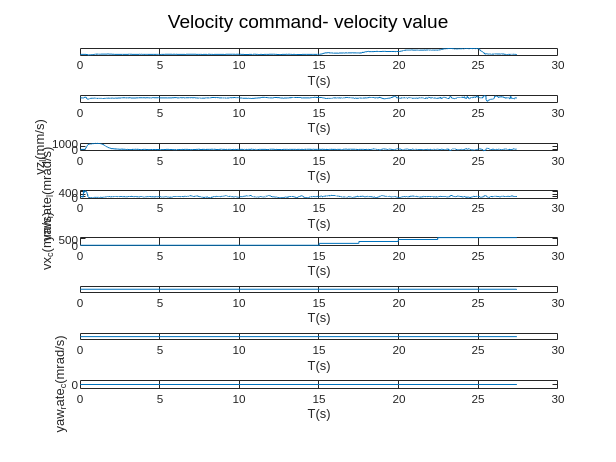

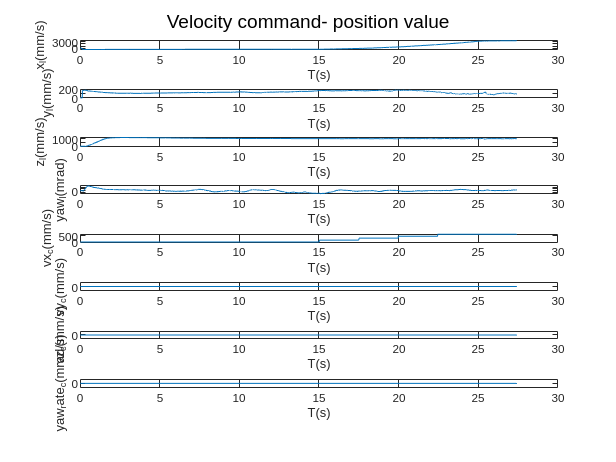

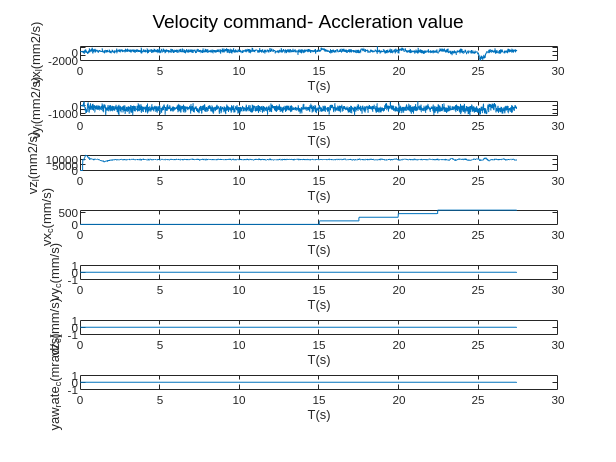


plot_result(T_vx_2)

## Remove total response


T_vx_1 = T_vx_1(T_vx_1.t >= 15.8198 & T_vx_1.t <= 26.6575,:);
T_vx_2 = T_vx_2(T_vx_2.t >= 14.6842 & T_vx_2.t <= 24.5053,:);
T_vy_1 = T_vy_1_(T_vy_1_.t >= 14.3473 & T_vy_1_.t <= 24.5856,:);


vx_1 =(T_vx_1.vx_i.*cos(deg2rad(T_vx_1.yaw_i)) + T_vx_1.vy_i.*sin(deg2rad(T_vx_1.yaw_i)))/1000;
vx_2 =(T_vx_2.vx_i.*cos(deg2rad(T_vx_2.yaw_i)) + T_vx_2.vy_i.*sin(deg2rad(T_vx_2.yaw_i)))/1000;
vy_1 =(-T_vy_1.vx_i.*sin(deg2rad(T_vy_1.yaw_i)) + T_vy_1.vy_i.*cos(deg2rad(T_vy_1.yaw_i)))/1000;

t_x_1 = (T_vx_1.t);
t_x_2 = (T_vx_2.t);
t_y_1 = (T_vy_1.t);

vx_1_c = (T_vx_1.vx_c_w)/1000;
vx_2_c = (T_vx_2.vx_c_w)/1000;
vy_1_c = (T_vy_1.vy_c_w)/1000;





Removing gain offset...
Removing time offset...


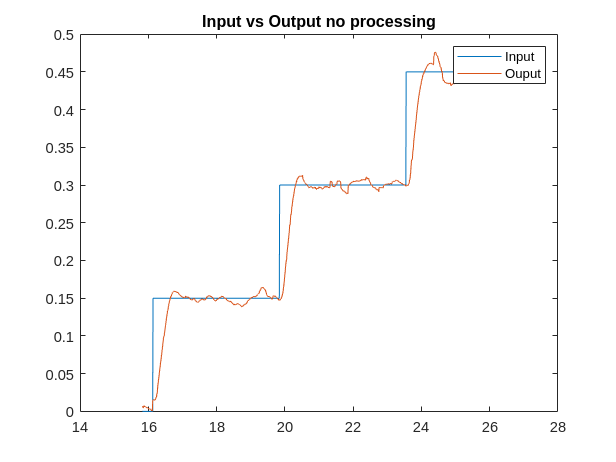

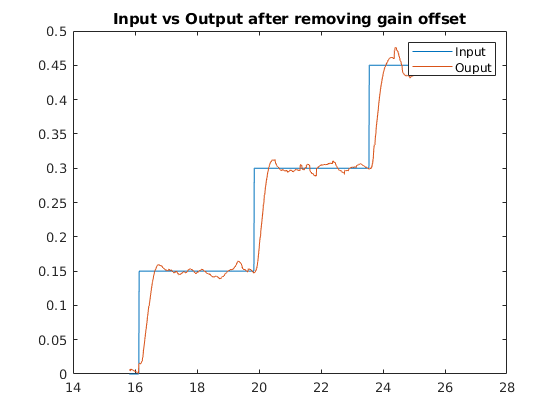

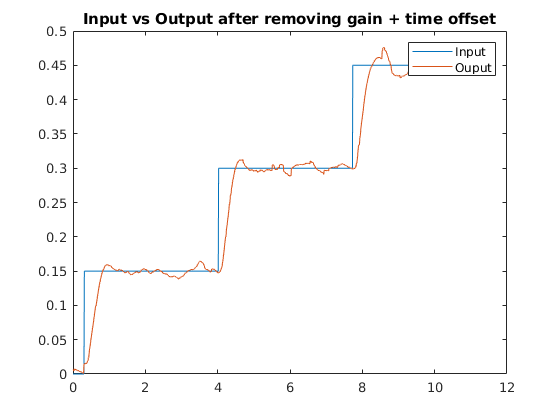

[t_1_x, i_1_x, o_1_x] = preprocess_data(t_x_1, vx_1_c, vx_1, true);

Removing gain offset...
Removing time offset...


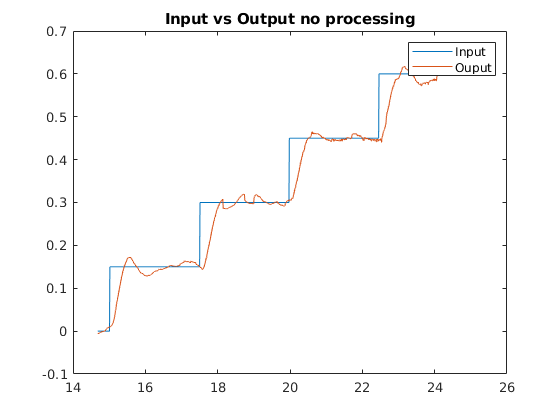

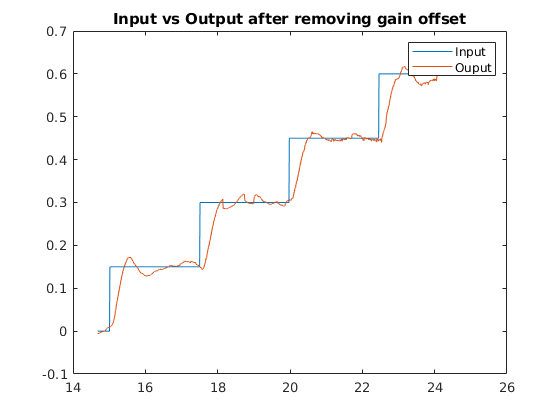

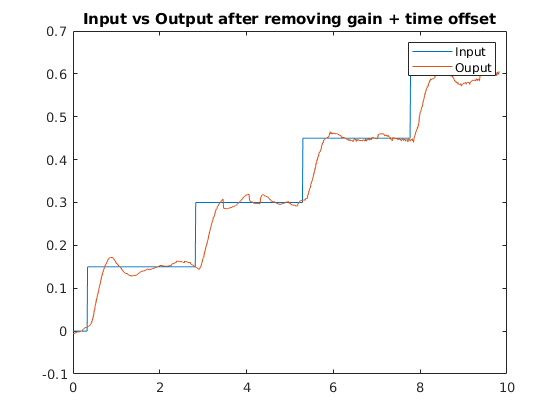

[t_2_x, i_2_x, o_2_x] = preprocess_data(t_x_2, vx_2_c, vx_2, true);

Removing gain offset...
Removing time offset...


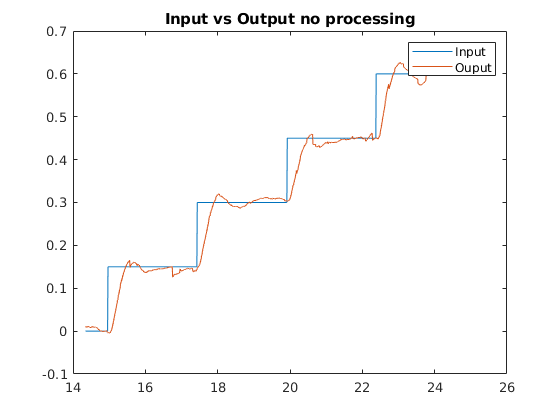

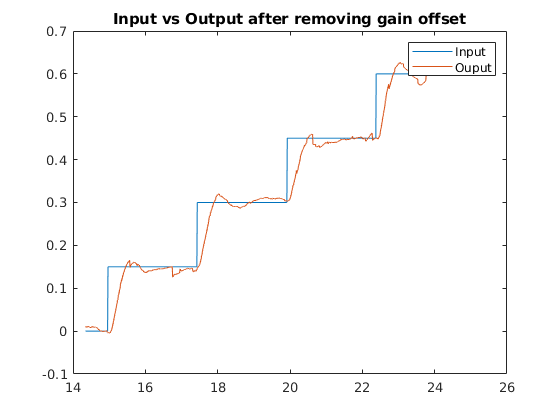

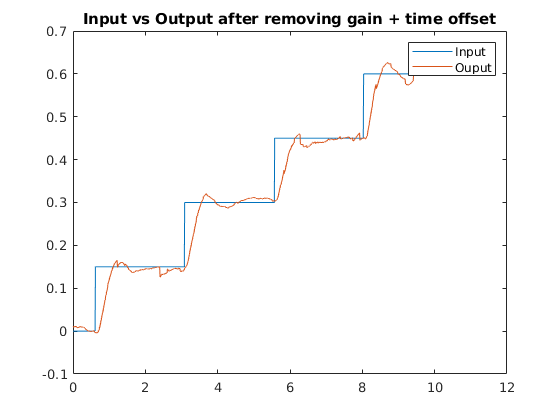

[t_1_y, i_1_y, o_1_y] = preprocess_data(t_y_1, vy_1_c, vy_1, true);

## Sampling time

Ts1 = mean(t_1_x(2:end)- t_1_x(1:end-1));
Ts2 = mean(t_2_x(2:end)- t_2_x(1:end-1));
Ts3 = mean(t_1_y(2:end)- t_1_y(1:end-1));

Ts_ = mean([Ts1 Ts2 Ts3]);
Ts = 0.01;




np = 2;
nz = 0;
data_vx1 = iddata(o_1_x,i_1_x, Ts);
data_vx2 = iddata(o_2_x,i_2_x, Ts);
data_vy = iddata(o_1_y,i_1_y, Ts);

sysx1 = tfest(data_vx1,np,nz);
sysx2 = tfest(data_vx2,np,nz)

sysx2 =
 
  From input "u1" to output "y1":
          33.62
  ---------------------
  s^2 + 7.488 s + 33.97
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "data_vx2".
Fit to estimation data: 93.8%                        
FPE: 0.0001188, MSE: 0.0001176                       


sysy = tfest(data_vy,np,nz)

sysy =
 
  From input "u1" to output "y1":
         34.83
  --------------------
  s^2 + 7.35 s + 35.04
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "data_vy".
Fit to estimation data: 94.79%                      
FPE: 9.499e-05, MSE: 9.405e-05                      


(9.405e-05)

ans = 9.4050e-05

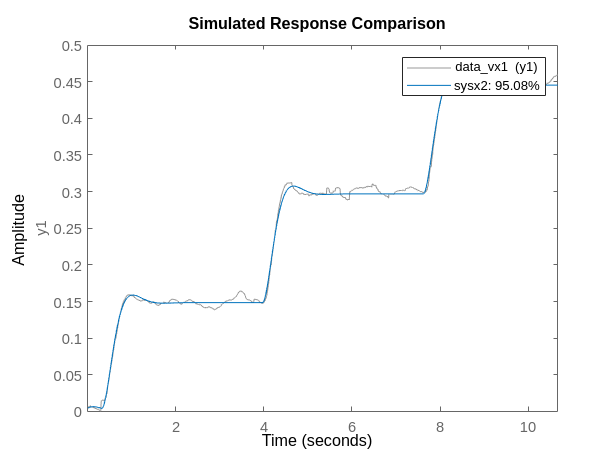

figure
compare(data_vx1,sysx2)

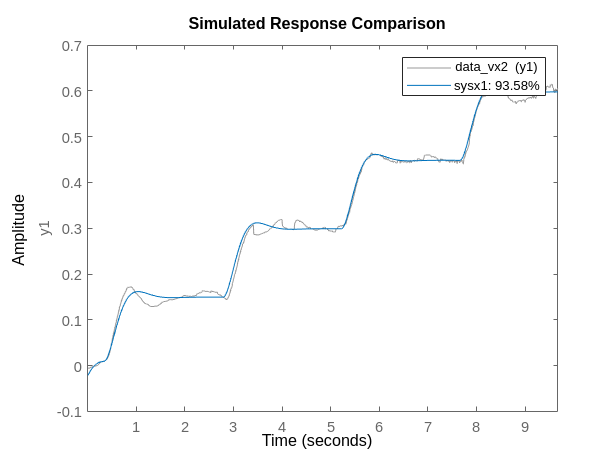

compare(data_vx2,sysx1)

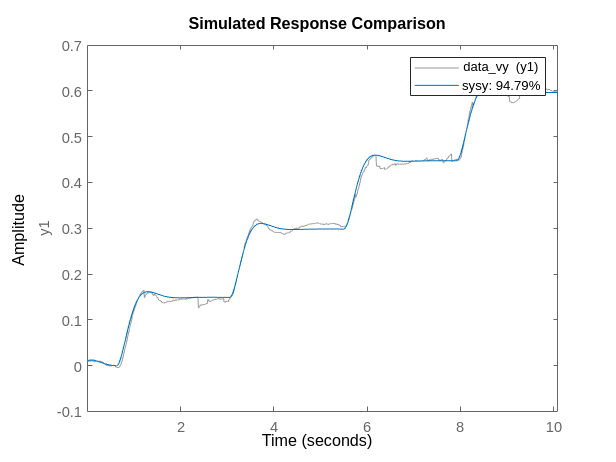

compare(data_vy,sysy)

## find a discrete model of the transfer function

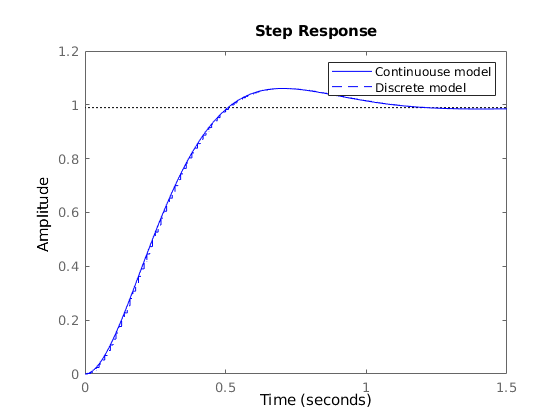

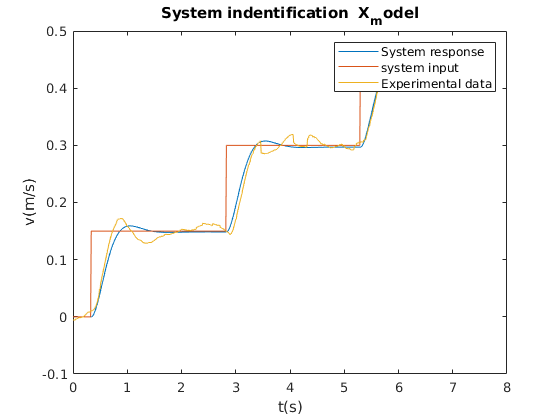

[d_sysx, std_errorx] = obtain_discrete_model_second_order(sysx2, true, Ts, t_2_x, i_2_x, o_2_x, 'X_model');

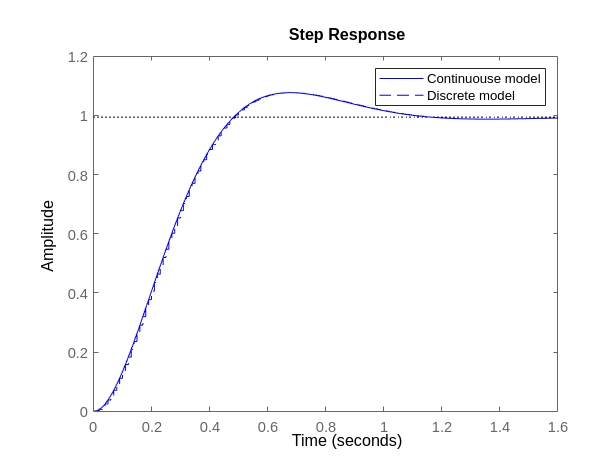

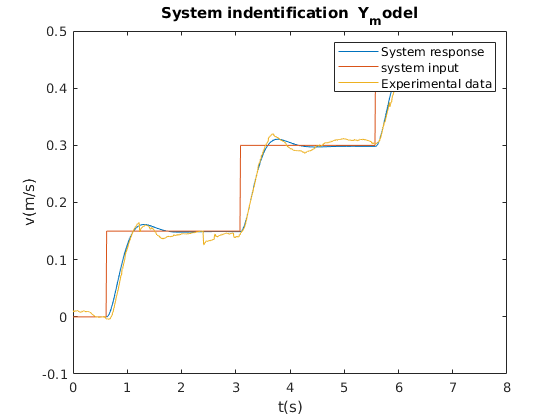

[d_sysy, std_errory] = obtain_discrete_model_second_order(sysy, true, Ts, t_1_y, i_1_y, o_1_y, 'Y_model');

eig(d_sysy.A)

ans =    0.9629 + 0.0447i
   0.9629 - 0.0447i



eig(d_sysx.A)

ans =    0.9623 + 0.0430i
   0.9623 - 0.0430i


## Error modeling


[x_ss,fit_ss,ic_ss] = compare(data_vx1,sysx2);
[x_ss2,fit_ssx,ic_ssx] = compare(data_vx2,sysx1);
[y_ss,fit_ssy,ic_ssy] = compare(data_vy,sysy);


stdx = std(data_vx1.OutputData-x_ss.OutputData)
stdx2 = std(data_vx2.OutputData-x_ss2.OutputData)
std_errorx = mean([stdx,stdx2])
std_errory = std(data_vy.OutputData-y_ss.OutputData)


% save 'models/ugv/second_order_model.mat' d_sysx d_sysy std_errorx std_errory sysx2 sysy

